% Параметры системы
M = 20; % масса тележки
m1 = 2; % масса 1-го груза
m2 = 1; % масса 2-го груза
l1 = 1; % длина 1-го маятника
l2 = 2; % длина 2-го маятника
g = 10; % ускорение свободного падения

% ВСВ
A = [0 1 0 0 0 0;
     0 0 m1*g/M 0 m2*g/M 0;
     0 0 0 1 0 0;
     0 0 (M+m1)*g/(M*l1) 0 m2*g/(M*l1) 0;
     0 0 0 0 0 1;
     0 0 m1*g/(M*l2) 0 (M+m2)*g/(M*l2) 0];

B = [0;
     1/M;
     0;
     1/(M*l1);
     0
     1/(M*l2)];

D = [0 0;
     1/(M*l1) 1/(M*l2);
     0 0;
     1/l1^2*(1/M+1/m1) 1/(M*l1*l2);
     0 0;
     1/(M*l1*l2) 1/l2^2*(1/M+1/m2)];

C = [1 0 0 0 0 0;
     0 0 1 0 0 0;
     0 0 0 0 1 0];

% 2.1. Анализ матриц
e = eig(A); % собственные числа
[v,D] = eig(A); % собственные векторы

% Управляемость
U = [B A*B A^2*B A^3*B A^4*B A^5*B];
rank(U);

% Наблюдаемость
V = [C; C*A; C*A^2; C*A^3; C*A^4; C*A^5];
rank(V);

% жорданово
[P_complex,J_complex] = jordan(A); % комплексное
[P, J]= cdf2rdf(P_complex,J_complex); % вещественное
% замена базиса
A_j = inv(P)*A*P;
B_j = inv(P)*B;

% 2.2. Передаточные функции
I = eye(6);
syms s
W = C*inv(s*I-A)*[B D];
[n, d] = numden(W(1,1));
[n, d] = numden(W(2,1));
[n, d] = numden(W(3,1));

[n, d] = numden(W(1,2));
[n, d] = numden(W(2,2));
[n, d] = numden(W(3,2));

[n, d] = numden(W(1,3));
[n, d] = numden(W(2,3));
[n, d] = numden(W(3,3));
W1 = tf(ss(A,B,C,0));
W2 = tf(ss(A,D,C,0));

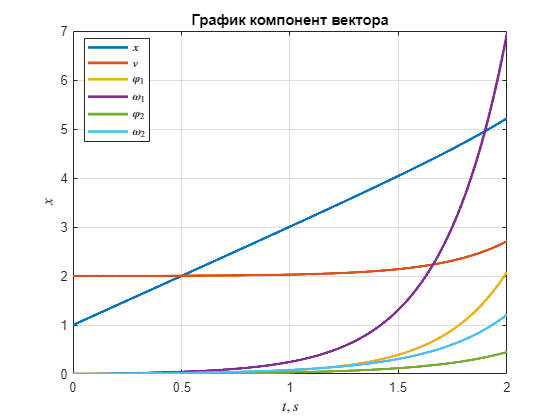

% начальные условия:
x_0 = 1;
v_0 = 2;
phi1_0 = 0.005;
w1_0 = 0;
phi2_0 = 0.006;
w2_0 = 0;
x0 = [x_0, v_0, phi1_0, w1_0, phi2_0, w2_0];


% 2.3. Линейное моделирование
plot(out.x_linear.Time, out.x_linear.Data, LineWidth=2), grid on
title("График компонент вектора")
xlabel('$t,s$', 'Interpreter','latex')
ylabel('$x$', 'Interpreter','latex')
legend('$x$', '$v$', '$\varphi_1$', '$\omega_1$', '$\varphi_2$', '$\omega_2$', 'Interpreter','latex')
legend("Position",[0.1506,0.66151,0.11786,0.24881])

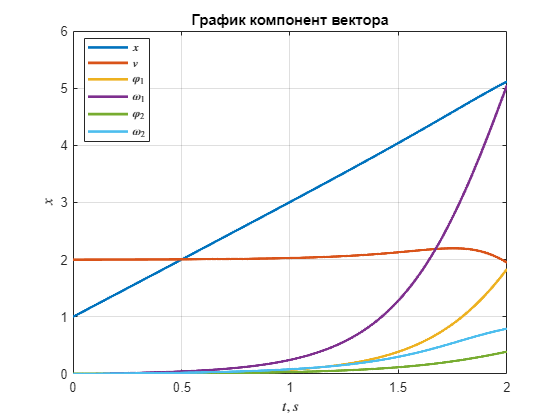


% 2.4. Нелинейное моделирование
plot(out.x_nonlinear.Time, out.x_nonlinear.Data, LineWidth=2), grid on
title("График компонент вектора")
xlabel('$t,s$', 'Interpreter','latex')
ylabel('$x$', 'Interpreter','latex')
legend('$x$', '$v$', '$\varphi_1$', '$\omega_1$', '$\varphi_2$', '$\omega_2$', 'Interpreter','latex')
legend("Position",[0.1506,0.66151,0.11786,0.24881])